# Getting data from simulink model for further processing

Clear our workspace and command window

clear
clc

Load system and set the mode to External

model = load_system('Model_for_frequency_estimating');
name = 'Model_for_frequency_estimating'

name = 'Model_for_frequency_estimating'

simMode = get_param(model,'SimulationMode')

simMode = 'external'

set_param(model,'SimulationMode','external')

Show blocks parameters

BlockPaths = find_system(model,'Type','Block')

BlockPaths = 	1.0e+04 *

    1.0317
    1.0319
    1.0324
    1.0325
    1.0351
    1.0352
    1.0353


BlockTypes = get_param(BlockPaths,'BlockType')

BlockTypes = 7×1 cell array
    {'S-Function'}
    {'SubSystem' }
    {'Scope'     }
    {'Scope'     }
    {'Sin'       }
    {'Outport'   }
    {'Outport'   }


Get parameters of Sin block to change it in further steps

get_param(name+"/Sine",'Amplitude')

Invalid Simulink object name: Model_for_frequency_estimating/Sine

Caused by:
    Error using Step1_Processing_and_Finding_TF (line 9)
    No block called 'Sine' could be found.

get_param(name+"/Sine",'Frequency')

Get all parameters of Sin Block

get_param(name+"/Sine",'ObjectParameters')

Make some constants for out model as Sample Time, Time of Running, Frequency and Amplitude of Sin Block

Ts = '0.01';
t = 1:10:100;
F = ([0.3;0.5;1;3;5;7;9;11;13;16])
A = 50.*ones(1,10)

Set parameter Frequency for Sin Block and check that it was setted

set_param(name+"/Sine",'Frequency',num2str(F(2,1)))
get_param(name+"/Sine",'Frequency')

Get Parameters for Status of Model and Stop Time

get_param(name, 'SimulationStatus')
get_param(name, 'StopTime')
set_param(name,'StopTime','20')
get_param(name, 'StopTime')

Switch off launching report 

set_param(name, 'GenerateReport', 'On')
set_param(name, 'LaunchReport', 'Off')

Make arrays for Input and Output of model with specified range

Inp = zeros(1700,length(A));
Out = zeros(1700,length(A));

Run out model with specified parameters and get Input and Output arrays

Pause is needed for writing to array and for while loop

for j=1:length(A)
    set_param(name,'SimulationCommand','start')
    set_param(name+"/Sine",'Amplitude',num2str(A(j)));
    set_param(name+"/Sine",'Frequency',num2str(F(j)))
    set_param(name+"/Sine",'SampleTime',Ts);
    while get_param(name, 'SimulationStatus') ~= "stopped"
        pause(0.1)
        Inp(:,j) = Input(1:1700,2);
        Out(:,j) = Output(1:1700,2);
    end
    pause(20)
end

Save time array and Input and Output arrays to mat file for further

Time_Data = Input(1:1700,1);
save('Input_data.mat','Inp');
save('Output_data.mat','Out');
save('Time_data.mat','Time_Data');


#### Step1. Preprocessing

Load our data

Input - Signal Volume (0..100)

Output - signal from Encoder (degrees)

load('Input_data.mat');
load('Output_data.mat');
load('Time_data.mat');

Detrend out data for futher processing

Speed_In = detrend(Inp)
Angle_Out = detrend(Out)

Filter out data

windowSize = 1; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;
Speed_In = filter(b,a,Speed_In);
Angle_Out = filter(b,a,Angle_Out);

Filter our data by smoothing

Speed_In = smoothdata(Speed_In,1,'sgolay');
Angle_Out = smoothdata(Angle_Out,1,'sgolay');

Filter by movmean

Speed_In = movmean(Speed_In,1,1)
Angle_Out = movmean(Angle_Out,1,1)

Estimate frequency from phase(angle) - Angle_Out as time derivative. Use Sample Time as step time

Measurement Unit - deg/sec(speed)

Angle_out_diff = diff(Angle_Out)./str2double(Ts)
Angle_out_diff = detrend(Angle_out_diff);

Create a time array for Angle_out_diff array

time = Time_Data(1:1699);

Convert to Radian

% Angle_out_diff = deg2rad(Angle_out_diff)
% Speed_in = deg2rad(Speed_In)

Fit Data and find coefficients of **Output** signal

a1 - magnitude, c1 - phase(rad), b1 - frequency(rad/s)

for i = 1:size(Angle_out_diff,2)
   [fitres,gog] = createFit(time,Angle_out_diff(:,i))
   Out_coef(i,1) = fitres.a1;
   Out_coef(i,2) = fitres.c1;
   Out_coef(i,3) = fitres.b1;
end

Fit Data and find coefficients of **Input** signal

for i = 1:size(Speed_In,2)
   [fitres,gog] = createFit(Time_Data,Speed_In(:,i))
   Inp_coef(i,1) = fitres.a1;
   Inp_coef(i,2) = fitres.c1;
   Inp_coef(i,3) = fitres.b1;
end

View our coefficients, **b1** must be almost equal

Out_coef

Out_coef =   264.5041   -1.5292    0.4513
  438.5783   -0.1121    0.5116
  445.5021    0.0817    0.9996
  456.7279   -0.3057    2.9596
  466.8059   -0.3827    5.1445
  418.5656   -0.7263    6.9537
  365.2279   -0.4540    9.2833
  281.8639    1.1172   10.8690
  284.0773   -0.4621   13.3261
  341.6694   -0.6941   15.9944


Inp_coef

Inp_coef =    27.5161   -1.5167    0.4506
   45.9146   -0.1191    0.5130
   46.4008    0.1314    0.9988
   49.5487   -0.1586    2.9594
   48.8940   -0.1637    5.1465
   46.4949   -0.4090    6.9537
   40.3344   -0.0831    9.2872
   33.7973    1.5962   10.8754
   34.9548    0.0988   13.3317
   46.8974   -0.0555   15.9996


Out_coef()

ans =   264.5041   -1.5292    0.4513
  438.5783   -0.1121    0.5116
  445.5021    0.0817    0.9996
  456.7279   -0.3057    2.9596
  466.8059   -0.3827    5.1445
  418.5656   -0.7263    6.9537
  365.2279   -0.4540    9.2833
  281.8639    1.1172   10.8690
  284.0773   -0.4621   13.3261
  341.6694   -0.6941   15.9944


Save arrays to files

save('Out_a1_c1_b1.mat','Out_coef')
save('Inp_a1_c1_b1.mat','Inp_coef')

#### Step 2. Find complex values of signals

Load files with coefficients

load Out_a1_c1_b1.mat
load Inp_a1_c1_b1.mat

Find complex coefficients of signals(imag and complex part)

In_complex = Inp_coef(:,1).*cos(Inp_coef(:,2)) + 1i*Inp_coef(:,1).*sin(Inp_coef(:,2));
Out_complex = Out_coef(:,1).*cos(Out_coef(:,2)) + 1i*Out_coef(:,1).*sin(Out_coef(:,2));

Estimating coefficient of transmitting

coeff = Out_complex./In_complex

coeff =    9.6119 - 0.1201i
   9.5518 + 0.0669i
   9.5893 - 0.4769i
   9.1182 - 1.3513i
   9.3193 - 2.0739i
   8.5528 - 2.8094i
   8.4395 - 3.2814i
   7.4013 - 3.8436i
   6.8815 - 4.3236i
   5.8498 - 4.3426i


Frequency estimating

freq_In = Inp_coef(:,3)

freq_In =     0.4506
    0.5130
    0.9988
    2.9594
    5.1465
    6.9537
    9.2872
   10.8754
   13.3317
   15.9996


period_In =1./ Inp_coef(:,3)

period_In =     2.2191
    1.9494
    1.0012
    0.3379
    0.1943
    0.1438
    0.1077
    0.0920
    0.0750
    0.0625



freq_Out = Out_coef(:,3)

freq_Out =     0.4513
    0.5116
    0.9996
    2.9596
    5.1445
    6.9537
    9.2833
   10.8690
   13.3261
   15.9944


period_Out = 1./Out_coef(:,3)

period_Out =     2.2160
    1.9547
    1.0004
    0.3379
    0.1944
    0.1438
    0.1077
    0.0920
    0.0750
    0.0625


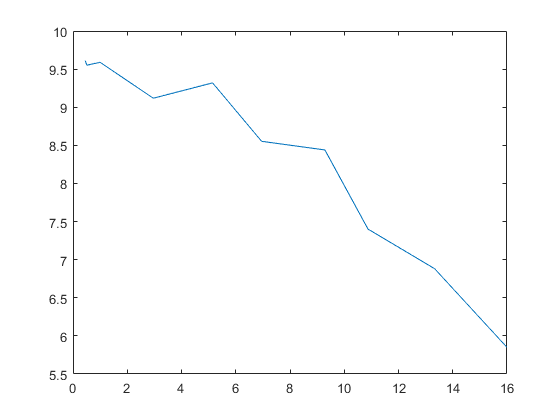

plot(freq_In,coeff)

scale = freq_In ./ freq_Out

almost equal - right estimating

#### Step3a. Plotting with System Identification Method and finding Transfer Function

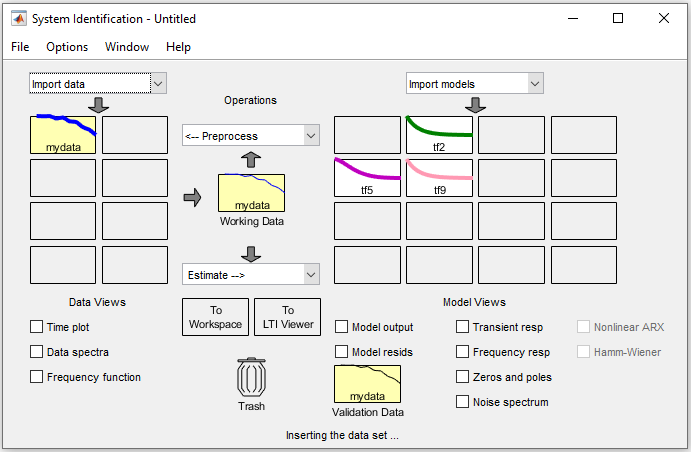

- Open **System Identification App **from **App **Tab and choose it from available apps.

- On the left side of the opened windows you can *Import *your data. In our case that's a *frequency-domain *data

- In the **Import Data **window specify type of your signal and Workspace Variables, also specify Data Information( sample time end etc.)

- Click **Import**

- Now you can see your data on the left side of windows in rectangle region. You can click on available *Data Views *to view your data( Time Plot, Data Spectra and Frequency Function)

- For further processing make sure that your data specified as Working Data(Section in the middle of the window) and as Validation Data(right side of the Window).

- Now you can click on drop-don list (*Estimate -->) *and choose what you are going to estimate with your data. In our case that's a (*Transfer Function Models)*

- Specify parameters like *NumOfPoles/NumOfZeros* in opened window and other properties.

- Click **Estimate**

- You can see imported model on the right side of the **System Identification App **in rectangle region.Double-Click on it to see its properties or  export your model to your workspace by clicking button **Export **in Data/model info window

- Also you can view your data by specifying type of Model View in **Model Views **section

- Finish

systemIdentification

#### Step3b. Transfer Function Estimation via function

Transfer Function Estimation via function **tfest(data,np,nz,opt) , ***where *data - time- or frequency -domain data ( *iddata *and *frd/idfrd object accordingly) , np * - NumOfPoles, *nz *- NumOfZeros, *opt - *option that specifies the estimation behavior

opt = tfestOptions;
opt.WeightingFilter = [];
Options.Display = 'on'; 
mydata = frd(coeff,freq_In);
tf = tfest(mydata, 1, 1,opt)
bode(mydata)
bode(tf)
tf.Denominator